# produce a PAH .airfoil file from a selig 1223

clear; close; clc;

## Initialize variables

fileName_original = "KL_sexy_sexy"

fileName_original = "KL_sexy_sexy"


filename = "PAH_"+ fileName_original

filename = "PAH_KL_sexy_sexy"

%filename = "PAH_KL_sexy_sexy" % PAH_selig 1223
%filename = " PAH_selig 1223"
PAH_relaxation_factor = 1.5 % 2 is half stiffness of original 4 is a quater of stiffness of original

PAH_relaxation_factor = 1.5000

## read the file

%airfoilData = fileread("Selig 1223.airfoil");
%airfoilData = fileread("KL_sexy_sexy.airfoil");
airfoilData = fileread(fileName_original+".airfoil");
%airfoilData = fileread("Wortmann FX LIII-142 Re#500k.airfoil");


airfoilData = split(airfoilData,newline)

airfoilData = 14×1 cell array
    {'[Airfoil]←'                                           }
    {'Name=KL sexy sexy 012 132f - ReNum 200k←'             }
    {'Data Source=Summary of Low Speed Airfoil Data Vol. 2←'}
    {'clalpha [1/rad]=7.16←'                                }
    {'alpha_o [deg]=-2←'                                    }
    {'c_l_o [-]=0.2←'                                       }
    {'alpha" [deg]=9.31281674008204←'                       }
    {'alpha* [deg]=7←'                                      }
    {'c_l* [-]=1←'                                          }
    {'alpha_c_l_max [deg]=16←'                              }
    {'c_l_max [-]=1.3←'                                     }
    {'alpha_post_S [deg]=18←'                               }
    {'c_l_post_S [-]=1.28←'                                 }
    {0×0 char                                                }



% extract the value from the file
name = string(extractBetween(airfoilData(2),"=",char(13)));
DataSource = string(extractBetween(airfoilData(3),"=",char(13)));

c_l_alpha = str2double(extractBetween(airfoilData(4),"=",char(13)));
for i = 4:13
    data(i-3) = str2double(extractBetween(airfoilData(i),"=",char(13)));
end
c_l_alpha = data(1);
alpha_0 = deg2rad(data(2));
c_l_0 = data(3);
alpha_prime = deg2rad(data(4));
alpha_star = deg2rad(data(5));
c_l_star = data(6);
alpha_c_l_max = deg2rad(data(7));
c_l_max = data(8);
alpha_post_stall = deg2rad(data(9));
c_l_post_stall = data(10);

% save into airfoil object
airfoil = Airfoil(name, DataSource, c_l_alpha, alpha_0, c_l_0, alpha_star,alpha_prime, c_l_star, alpha_c_l_max, c_l_max, alpha_post_stall, c_l_post_stall)

airfoil =   Airfoil with properties:

                name: "KL sexy sexy 012 132f - ReNum 200k"
          dataSource: "Summary of Low Speed Airfoil Data Vol. 2"
           c_l_alpha: 7.1600
             alpha_0: -0.0349
               c_l_0: 0.2000
          alpha_star: 0.1222
         alpha_prime: 0.1625
            c_l_star: 1
       alpha_c_l_max: 0.2793
             c_l_max: 1.3000
    alpha_post_stall: 0.3142
      c_l_post_stall: 1.2800


## plot airfoil

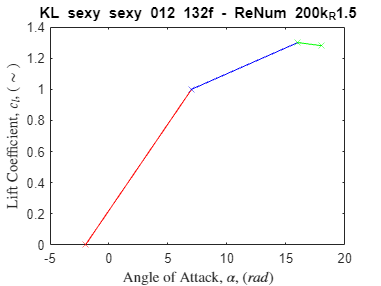

figure;
alphas = rad2deg([airfoil.alpha_0, airfoil.alpha_star, airfoil.alpha_c_l_max, airfoil.alpha_post_stall]);
c_ls = [0, airfoil.c_l_star, airfoil.c_l_max, airfoil.c_l_post_stall];

plot(alphas(1:2), c_ls(1:2),"r-x"); % plot the linear region
hold on;
plot(alphas(2:3), c_ls(2:3),"b-x"); % approximate the nonlinear region
plot(alphas(3:4), c_ls(3:4),"g-x");
title(airfoil.name + "_R" + PAH_relaxation_factor);
xlabel("Angle of Attack, $\alpha$, ($rad$)",Interpreter="latex");
ylabel("Lift Coefficient, $c_{l}$, ($\sim$)",Interpreter="latex");

## now produce a PAH verison

% we know that the C_L_mad is unchanged 
% lets just try streching it by a ratio of 2:1 around c_l_max

alpha_c_l_max_PAH = airfoil.alpha_c_l_max; % stall remins unchanged

% lift curve slope
alpha_0_PAH = airfoil.alpha_c_l_max - (airfoil.alpha_c_l_max-airfoil.alpha_0)*PAH_relaxation_factor; % half the lift curve slope
c_l_alpha_PAH = airfoil.c_l_alpha/PAH_relaxation_factor

c_l_alpha_PAH = 4.7733

% nonlinear region
alpha_star_PAH = airfoil.alpha_c_l_max - (airfoil.alpha_c_l_max-airfoil.alpha_star)*PAH_relaxation_factor; % half the lift curve slope
% post stall
alpha_post_stall_PAH = airfoil.alpha_c_l_max - (airfoil.alpha_c_l_max-airfoil.alpha_post_stall)*PAH_relaxation_factor; % half the lift curve slope
% alpha prime
alpha_prime_PAH = airfoil.alpha_c_l_max - (airfoil.alpha_c_l_max-airfoil.alpha_prime)*PAH_relaxation_factor; % half the lift curve slope

airfoil_PAH = Airfoil("PAH_"+name+"_R"+PAH_relaxation_factor, DataSource, c_l_alpha_PAH, alpha_0_PAH, c_l_0, alpha_star_PAH, alpha_prime, c_l_star, alpha_c_l_max, c_l_max, alpha_post_stall_PAH, c_l_post_stall)

airfoil_PAH =   Airfoil with properties:

                name: "PAH_KL sexy sexy 012 132f - ReNum 200k_R1.5"
          dataSource: "Summary of Low Speed Airfoil Data Vol. 2"
           c_l_alpha: 4.7733
             alpha_0: -0.1920
               c_l_0: 0.2000
          alpha_star: 0.0436
         alpha_prime: 0.1625
            c_l_star: 1
       alpha_c_l_max: 0.2793
             c_l_max: 1.3000
    alpha_post_stall: 0.3316
      c_l_post_stall: 1.2800


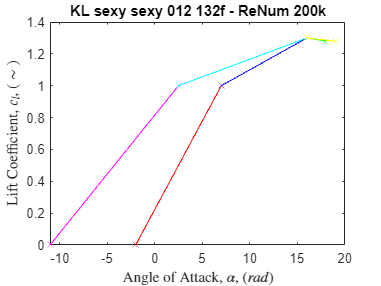


alphas = rad2deg([airfoil_PAH.alpha_0, airfoil_PAH.alpha_star, airfoil_PAH.alpha_c_l_max, airfoil_PAH.alpha_post_stall]);
c_ls = [0, airfoil_PAH.c_l_star, airfoil_PAH.c_l_max, airfoil_PAH.c_l_post_stall];

plot(alphas(1:2), c_ls(1:2),"m-x"); % plot the linear region
hold on;
plot(alphas(2:3), c_ls(2:3),"c-x"); % approximate the nonlinear region
plot(alphas(3:4), c_ls(3:4),"y-x");
title(airfoil.name);
xlabel("Angle of Attack, $\alpha$, ($rad$)",Interpreter="latex");
ylabel("Lift Coefficient, $c_{l}$, ($\sim$)",Interpreter="latex");

## save airfoil

airfoil_PAH.createAirfoilFile(filename + "_R" + PAH_relaxation_factor + ".airfoil")
